# FFT 한번에 돌려놓기

clear 
% 현재 디렉토리

d = dir;


% 폴더만 필터링합니다.

isub = [d(:).isdir];
% '.'과 '..'을 제외한 폴더 이름만 가져옵니다.

folderNames = {d(isub).name}';
folderNames(ismember(folderNames,{'.','..'})) = [];

% 현재 폴더의 경로를 저장합니다.
currentFolder = pwd;


% 각 폴더에 차례로 들어가서 작업을 수행합니다.
tic
for ii = 1:length(folderNames)
    % 폴더로 이동
    cd(folderNames{ii});

## Get all imges

    exosome=dir("*.tif");
    [s,~]=size(exosome);

## Check the turn on point

    tic
    chs=700;
    window=chs:1000;
    [~,w]=size(window);
    IntS=zeros([1,w]);
    for i=window(1):window(end)
        IntS(i-window(1)+1)=sum(sum(im2gray(imread(exosome(i).name))));
    end

    plot(window,IntS)
    toc


경과 시간은 5.296518초입니다.


    L_ind=find(IntS==max(IntS))
    [mx_nm,~]=size(L_ind);

L_ind = 86

    if mx_nm<2

## Check the first image

        LO=chs+L_ind;
        I=im2gray(imread(exosome(LO).name));
        % I=im2gray(imread(exosome(LO)).name))
        [i1, i2]=size(I);
        title("First image snap shot")
        imshow(10*mat2gray(I))
        % axis on


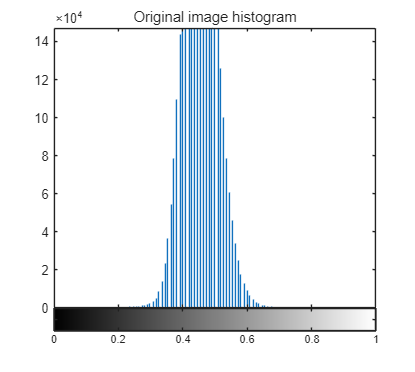

        imhist(mat2gray(I))
        title("Original image histogram")


## Sampling rate

        Sr=3;
        Sr_e=round(s/Sr);
        exosome_time_stack_SR=zeros([i1, i2, Sr_e]);

        
        tic
        parfor oo=1:Sr_e
            exosome_time_stack_SR(:,:,oo)=im2gray(imread(exosome(1+(oo-1)*Sr).name));
            % exosome_time_stack_SR(:,:,oo)=medfilt2(im2gray(imread(exosome(1+(oo-1)*Sr).name)));
        end
        toc

'Processes' 프로파일을 사용하여 병렬 풀(parpool)을 시작하는 중...
24개의 워커가 있는 병렬 풀에 연결됨


경과 시간은 57.707363초입니다.


## FFT settings

        Fs = round(40/Sr);            % Sampling frequency
        T = 1/Fs;             % Sampling period
        % Length of signal
        L = Sr_e;
        if mod(L,2) == 1
            L=Sr_e-1;
        end

        t = (0:L-1)*T;        % Time vector

## FFT

        tic
        exosome_frequency_stack=zeros([i1, i2, (L/2)+1]);
        parfor i=1:i1
            for j=1:i2
                ex_fft_c=fft(exosome_time_stack_SR(i,j,:));
                ex_fft_abs=abs(ex_fft_c/L);
                ex_fft=ex_fft_abs(1:L/2+1);
                ex_fft(2:end-1)=2*ex_fft(2:end-1);
                exosome_frequency_stack(i,j,:)=ex_fft;
            end
        end
        toc

    end
    % 원래 폴더로 돌아옵니다.
    cd(currentFolder);


    if mx_nm<2
        % FFT 결과 저장
        saveFileName = fullfile(currentFolder,sprintf('%s_exosome_frequency_stack.mat', folderNames{ii}));
        save(saveFileName, 'exosome_frequency_stack','-v7.3');
    end

end

경과 시간은 187.229400초입니다.


toc

경과 시간은 796.196460초입니다.
